# NB-IoT simulation

## ofdm parameters

clear
numSC=12;%number subcarriers, nbiot=12
numSym=42;%number ofdm symbols, nbiot=grouped 7 per frame but more for this sim
SCS=15e3;%subcarrier spacing, nbiot=15kHz


## simulation parameters

dataLength=numSC*numSym*2;
randomData=true;
nLoops=10;
filtersOn=false;
plotSpec=false;
maxSNR=25;
dopplerShift=0e3;%doppler shift geeft problemen in code!

## transmission


%base message
if randomData
    messageBits= randi([0 1],dataLength,1)
else
    messageBits=ones(dataLength,1)
end

messageBits =      0
     1
     0
     1
     0
     1
     1
     1
     0
     1



%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      1
     1
     1
     3
     1
     3
     2
     0
     0
     2


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =   -0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
   0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i


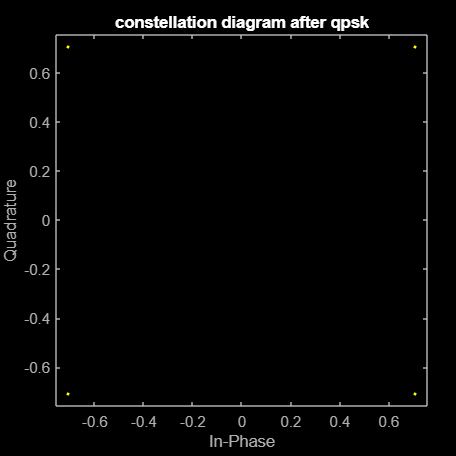

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

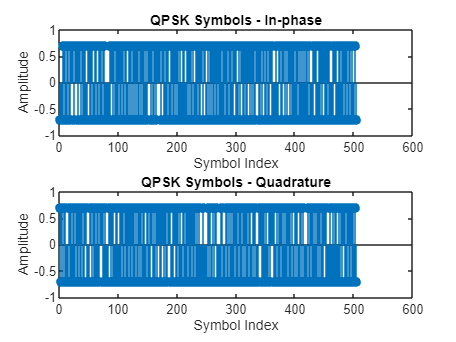


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


% numSC=12;% # subcarriers
% numSym=21;% # ofdm symbols
% SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
% t = (0:SPS-1) / samplingRate; %time vector

ofdmSignal = zeros(1, numSym * SPS);
cpLen=round(SPS/4);%cyclic prefix length
t=(symbolDuration/(SPS+cpLen):symbolDuration/(SPS+cpLen):(symbolDuration)*numSym);%time for each sample


ofdmMatrix = zeros(numSC,numSym);%12x7 in nbiot
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =   -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i
  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.707

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.0000 + 0.1179i  -0.2357 + 0.1179i  -0.1179 + 0.0000i   0.2357 + 0.0000i   0.1179 + 0.0000i  -0.1179 + 0.1179i   0.2357 + 0.0000i   0.3536 - 0.1179i   0.0000 - 0.2357i  -0.3536 + 0.1179i  -0.1179 - 0.2357i  -0.1179 - 0.1179i  -0.1179 + 0.4714i   0.0000 + 0.2357i  -0.1179 + 0.2357i   0.3536 + 0.1179i   0.0000 - 0.1179i   0.1179 - 0.1179i  -0.1179 + 0.0000i   0.1179 + 0.0000i  -0.2357 - 0.1179i   0.1179 + 0.4714i   0.3536 - 0.2357i   0.0000 - 0.1179i  -0.2357 - 0.1179i   0.2357 + 0.1179i  -0.2357 - 0.1179i   0.1179 + 0.2357i   0.0000 - 0.1179i  -0.1179 + 0.1179i   0.3536 + 0.0000i   0.1179 + 0.1179i  -0.1179 + 0.0000i  -0.1179 + 0.0000i   0.2357 - 0.2357i   0.1179 + 0.0000i   0.1179 + 0.1179i   0.1179 - 0.1179i   0.0000 + 0.0000i   0.0000 - 0.1179i   0.0000 - 0.1179i  -0.2357 - 0.3536i
   0.2041 - 0.2041i  -0.2788 - 0.0431i  -0.3378 + 0.2630i   0.2473 - 0.1610i  -0.0863 - 0.4398i  -0.2630 - 0.2199i  -0.0589 + 0.1336i  -0.0589 + 0.3378i  -0.2788 + 0.2788i  -0.1021 + 0.0273i   0.1

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.0000 + 0.1179i  -0.2357 + 0.1179i  -0.1179 + 0.0000i   0.2357 + 0.0000i   0.1179 + 0.0000i  -0.1179 + 0.1179i   0.2357 + 0.0000i   0.3536 - 0.1179i   0.0000 - 0.2357i  -0.3536 + 0.1179i  -0.1179 - 0.2357i  -0.1179 - 0.1179i  -0.1179 + 0.4714i   0.0000 + 0.2357i  -0.1179 + 0.2357i   0.3536 + 0.1179i   0.0000 - 0.1179i   0.1179 - 0.1179i  -0.1179 + 0.0000i   0.1179 + 0.0000i  -0.2357 - 0.1179i   0.1179 + 0.4714i   0.3536 - 0.2357i   0.0000 - 0.1179i  -0.2357 - 0.1179i   0.2357 + 0.1179i  -0.2357 - 0.1179i   0.1179 + 0.2357i   0.0000 - 0.1179i  -0.1179 + 0.1179i   0.3536 + 0.0000i   0.1179 + 0.1179i  -0.1179 + 0.0000i  -0.1179 + 0.0000i   0.2357 - 0.2357i   0.1179 + 0.0000i   0.1179 + 0.1179i   0.1179 - 0.1179i   0.0000 + 0.0000i   0.0000 - 0.1179i   0.0000 - 0.1179i  -0.2357 - 0.3536i
   0.2041 - 0.2041i  -0.2788 - 0.0431i  -0.3378 + 0.2630i   0.2473 - 0.1610i  -0.0863 - 0.4398i  -0.2630 - 0.2199i  -0.0589 + 0.1336i  -0.0589 + 0.3378i  -0.2788 + 0.2788i  -0.


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.0000 + 0.1179i
   0.2041 - 0.2041i
  -0.2788 + 0.3967i
  -0.2357 + 0.1179i
  -0.2788 - 0.1610i
  -0.2041 + 0.2041i
   0.0000 + 0.1179i
  -0.0863 - 0.2357i
  -0.0747 + 0.0431i
   0.0000 + 0.3536i


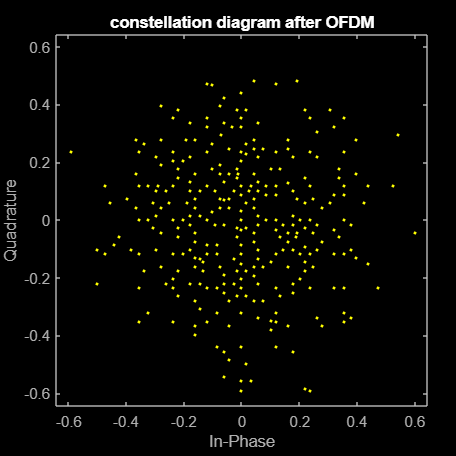

% plot ofdm signal

if plotSpec 
figure
window=hamming(7);
spectrogram(timeDomainSymbols,window,round(length(window)/2),BW)
end

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

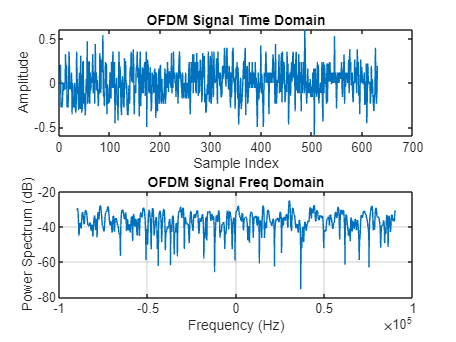


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

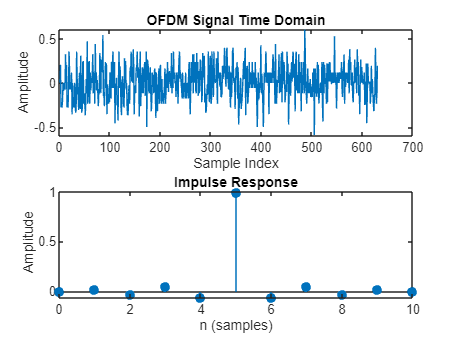

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

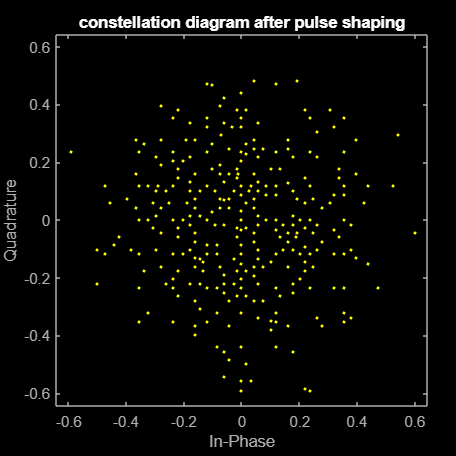

if filtersOn
    txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');
else
    txSignalShaped = txSignalUpsampled;

end

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

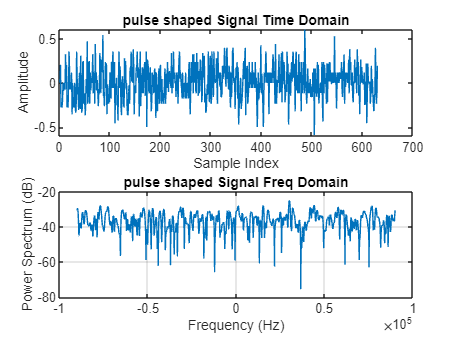


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

een vaste doppler shift zal in deze simulatie geen verschil maken, heel het signaal verschuift in freq domein maar uiteindelijk wordt de 180 kHz toch in 12 carriers opgesplitst,

varierende doppler shift zal wss wel effect hebben?

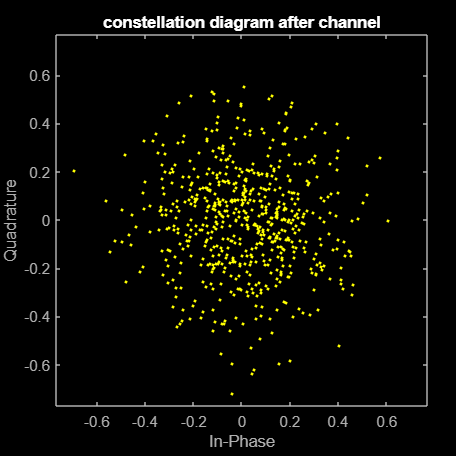

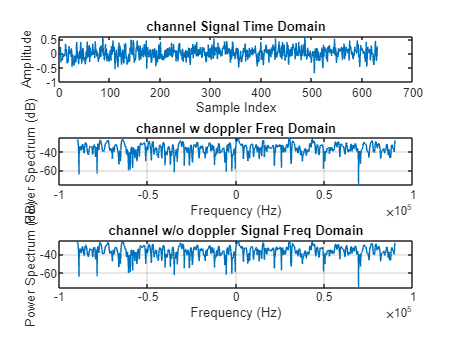

for counter=1:nLoops
%check filters, error rate is te hoog?

dopplerEffect = exp(1i * 2 * pi * dopplerShift * t);
txSignalDopplerShifted = txSignalUpsampled .* transpose(dopplerEffect);

SNR=20-(nLoops-counter);
% rxSignal=awgn(txSignalShaped,SNR);


rxSignal=awgn(txSignalDopplerShifted,SNR);
rxSignal2=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

if counter==nLoops %only plot in last loop
    % Plot the time domain signal after channel
    figure
    scatterplot(rxSignal)
    title('constellation diagram after channel');
    
    % Plot the time domain signal
    figure;
    subplot(3,1,1);
    plot(real(rxSignal));
    title('channel Signal Time Domain');
    xlabel('Sample Index');
    ylabel('Amplitude');
    
    [pxx,f] = pspectrum(rxSignal,samplingRate);
    subplot(3,1,2);
    plot(f,pow2db(pxx))
    grid on
    title('channel w doppler Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')

    [pxx,f] = pspectrum(rxSignal,samplingRate);
    subplot(3,1,3);
    plot(f,pow2db(pxx))
    grid on
    title('channel w/o doppler Signal Freq Domain');
    xlabel('Frequency (Hz)')
    ylabel('Power Spectrum (dB)')
end

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
if filtersOn
    matchedFilter = rcosdesign(rolloff, span, L);
    rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
else
    rxSignalFiltered = rxSignal;

end

rxSignalFiltered

rxSignalFiltered =    0.0809 + 0.2591i
   0.5125 - 0.1635i
  -0.4190 + 0.2860i
  -0.4812 + 0.1722i
  -0.0658 - 0.0161i
  -0.4471 + 0.1400i
   0.0125 - 0.0549i
  -0.1524 - 0.2334i
  -0.0402 - 0.1134i
  -0.0343 + 0.1216i


rxSignalFiltered =   -0.0019 - 0.0226i
   0.4780 - 0.3743i
  -0.3926 + 0.2010i
  -0.2353 + 0.4772i
  -0.5171 - 0.3133i
  -0.5696 + 0.4552i
   0.1263 - 0.2026i
  -0.2691 - 0.4017i
  -0.2693 + 0.1024i
  -0.1797 + 0.2476i


rxSignalFiltered =   -0.0706 + 0.1932i
   0.2368 - 0.2549i
  -0.3756 + 0.4912i
  -0.3007 + 0.0196i
  -0.2070 - 0.3081i
  -0.2826 + 0.3334i
   0.3263 + 0.2671i
   0.2024 - 0.2539i
  -0.1118 + 0.1647i
   0.0494 + 0.2957i


rxSignalFiltered =   -0.2249 + 0.0644i
   0.3785 - 0.2236i
  -0.2465 + 0.1758i
  -0.1964 + 0.1702i
  -0.1248 - 0.3375i
  -0.0668 + 0.0703i
  -0.2852 - 0.1164i
  -0.0124 - 0.2074i
  -0.0413 - 0.1831i
  -0.0594 + 0.4359i


rxSignalFiltered =    0.1169 + 0.1635i
   0.4230 - 0.5108i
  -0.1032 + 0.4374i
  -0.4339 + 0.1354i
  -0.1524 - 0.3806i
  -0.1391 + 0.2408i
   0.0228 + 0.0735i
  -0.0241 - 0.2620i
  -0.0674 + 0.2979i
   0.0283 + 0.5513i


rxSignalFiltered =   -0.0636 + 0.1785i
   0.4066 - 0.1856i
  -0.3997 + 0.4644i
  -0.1790 + 0.2141i
  -0.3403 - 0.0803i
  -0.0487 + 0.3604i
  -0.0824 - 0.0317i
   0.1887 - 0.0402i
  -0.2536 + 0.0401i
  -0.1320 + 0.1695i


rxSignalFiltered =   -0.0402 + 0.1704i
   0.2302 - 0.2494i
  -0.2325 + 0.3519i
  -0.3301 + 0.0852i
  -0.4302 - 0.0185i
  -0.1099 + 0.1178i
   0.0546 - 0.0595i
  -0.0762 - 0.2424i
  -0.0646 + 0.0908i
   0.0924 + 0.3842i


rxSignalFiltered =   -0.0587 + 0.1046i
   0.0351 - 0.2122i
  -0.2785 + 0.2775i
  -0.2795 + 0.1107i
  -0.0742 - 0.1849i
  -0.0401 + 0.2564i
  -0.0461 + 0.1930i
  -0.0962 - 0.2973i
  -0.0328 - 0.1058i
   0.0612 + 0.4170i


rxSignalFiltered =   -0.0162 - 0.0007i
   0.1905 - 0.1829i
  -0.3144 + 0.2896i
  -0.2490 + 0.1142i
  -0.2192 - 0.2647i
  -0.1829 + 0.3528i
   0.0795 + 0.0412i
  -0.2478 - 0.2131i
  -0.1779 + 0.0117i
  -0.0910 + 0.3316i


rxSignalFiltered =    0.0419 + 0.0419i
   0.2195 - 0.1298i
  -0.3077 + 0.4307i
  -0.2177 + 0.1815i
  -0.1388 - 0.1857i
  -0.2422 + 0.1814i
  -0.0238 - 0.0040i
  -0.1273 - 0.2652i
  -0.0950 + 0.0334i
  -0.0206 + 0.3814i


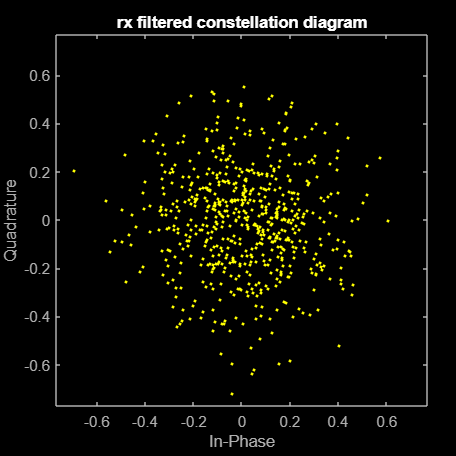


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);
if counter==nLoops
    figure;
    scatterplot(rxSignalFiltered);
    title('rx filtered constellation diagram');
end


%cp
% rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.0809 + 0.2591i  -0.0788 + 0.1831i  -0.1156 + 0.3275i   0.3603 - 0.0784i  -0.3210 - 0.0693i  -0.1943 + 0.3107i  -0.1064 - 0.0717i   0.6108 - 0.2275i   0.0588 + 0.1182i  -0.6327 - 0.1093i  -0.0354 - 0.1201i   0.0958 + 0.0297i  -0.2732 + 0.6978i  -0.3574 + 0.3249i  -0.3397 + 0.2760i   0.2659 + 0.0858i   0.0663 - 0.3265i   0.3777 - 0.3171i  -0.0607 - 0.2263i  -0.0740 - 0.0367i  -0.2971 - 0.1009i   0.2475 + 0.4114i   0.2753 - 0.3126i  -0.2416 + 0.1321i  -0.1577 - 0.4852i   0.2151 + 0.3188i  -0.5788 + 0.0720i   0.1045 + 0.5686i   0.1012 - 0.1959i  -0.3252 + 0.1208i   0.4177 - 0.4310i   0.0910 + 0.1740i  -0.2354 - 0.1792i  -0.3650 + 0.1530i   0.3983 - 0.2009i   0.2225 + 0.1259i   0.0611 + 0.1869i   0.1118 - 0.2567i  -0.0107 + 0.1394i   0.2438 - 0.2258i  -0.1413 - 0.3744i  -0.2903 - 0.2596i
   0.5125 - 0.1635i  -0.3616 + 0.2423i  -0.2044 + 0.4193i   0.4266 + 0.0663i  -0.0069 - 0.4890i  -0.3151 - 0.1317i  -0.2659 + 0.3509i  -0.1382 + 0.0101i  -0.3945 - 0.0007i  -0.1548 - 

rxSymbolsWithCP =   -0.0019 - 0.0226i  -0.3454 + 0.3051i   0.2043 - 0.2495i  -0.0448 - 0.2102i   0.4810 + 0.5673i  -0.2674 - 0.2848i   0.2060 - 0.1208i   0.4247 - 0.0158i   0.3440 - 0.1666i  -0.6081 + 0.3655i  -0.3292 - 0.1737i  -0.0694 - 0.0342i  -0.2209 + 0.6794i   0.0777 + 0.3563i  -0.0800 - 0.0658i   0.5616 + 0.2378i  -0.1151 - 0.1880i  -0.2691 + 0.0371i  -0.2901 + 0.1603i  -0.1273 - 0.1326i  -0.1472 + 0.1750i   0.5542 + 0.5052i   0.3700 - 0.1356i   0.3639 - 0.2928i  -0.2262 + 0.0190i   0.3688 + 0.1642i  -0.3299 - 0.1680i   0.3514 + 0.2262i   0.3033 - 0.0930i  -0.1016 + 0.1227i   0.3464 + 0.0498i   0.3068 + 0.0986i  -0.0798 - 0.4089i  -0.1725 + 0.2446i   0.0582 - 0.2173i   0.1202 + 0.1716i  -0.0073 - 0.1907i   0.0440 - 0.3185i   0.3338 + 0.2344i  -0.0584 - 0.3544i   0.0199 - 0.0403i  -0.0120 - 0.3612i
   0.4780 - 0.3743i  -0.5907 - 0.1805i  -0.3716 + 0.4664i   0.0248 - 0.1477i  -0.3111 - 0.4485i  -0.6385 - 0.4469i   0.3182 + 0.0314i  -0.2091 + 0.5232i  -0.0937 + 0.4481i  -0.0919 + 

rxSymbolsWithCP =   -0.0706 + 0.1932i  -0.3096 + 0.2119i  -0.0421 + 0.1324i   0.0889 + 0.1367i   0.0076 - 0.0547i  -0.0313 + 0.2142i   0.4834 - 0.0778i   0.3562 - 0.2301i  -0.0285 - 0.0593i  -0.4281 + 0.2603i   0.1467 - 0.0696i  -0.1494 - 0.0734i   0.1112 + 0.5020i   0.0605 + 0.4502i   0.0288 + 0.1006i   0.6622 + 0.1294i  -0.2112 - 0.1544i   0.0559 - 0.1913i  -0.2086 + 0.1010i   0.0944 - 0.1259i  -0.3984 - 0.0506i  -0.0236 + 0.6738i   0.2062 - 0.3598i  -0.2499 - 0.0840i   0.1851 - 0.2262i   0.3589 + 0.0876i  -0.1729 - 0.0276i   0.1428 + 0.5082i   0.1108 + 0.1340i   0.0378 + 0.0476i   0.2329 - 0.1286i   0.1811 + 0.3431i  -0.1083 + 0.1402i  -0.0080 - 0.0775i   0.1060 - 0.2688i   0.1461 + 0.0235i  -0.0888 + 0.2318i   0.2215 - 0.1354i   0.0333 + 0.0245i   0.0320 + 0.2184i   0.1581 - 0.1738i  -0.2202 - 0.5124i
   0.2368 - 0.2549i  -0.0831 - 0.0583i  -0.4317 + 0.3478i  -0.0869 - 0.2369i  -0.3203 - 0.3165i  -0.2693 - 0.1083i  -0.1017 + 0.1948i  -0.1824 + 0.3556i  -0.2199 + 0.5385i  -0.0289 + 

rxSymbolsWithCP =   -0.2249 + 0.0644i  -0.0701 + 0.2097i  -0.1410 - 0.1125i   0.3957 - 0.0451i   0.0882 + 0.0504i  -0.2624 + 0.1970i   0.0402 - 0.0406i   0.0326 - 0.1167i  -0.3348 - 0.0072i  -0.3601 + 0.2751i   0.0469 - 0.4575i  -0.1130 - 0.1856i  -0.1978 + 0.6422i   0.2293 + 0.1640i  -0.3816 + 0.3052i   0.4094 + 0.1638i   0.1091 - 0.1285i   0.0790 - 0.2140i  -0.2288 + 0.0268i   0.2535 + 0.0560i  -0.4361 - 0.0214i  -0.2024 + 0.4830i   0.4855 - 0.2499i   0.0695 - 0.1160i  -0.1534 - 0.1954i   0.2094 + 0.0095i  -0.0223 + 0.0172i   0.2369 + 0.4059i   0.1183 + 0.0565i  -0.2480 + 0.2743i   0.3121 - 0.0872i  -0.0758 + 0.2920i  -0.3480 - 0.0168i  -0.0237 + 0.1350i   0.2186 - 0.0342i   0.2512 + 0.1287i  -0.2370 + 0.3572i  -0.1863 - 0.2045i  -0.1898 - 0.0012i   0.0741 - 0.2365i  -0.0027 - 0.0727i  -0.2260 - 0.4370i
   0.3785 - 0.2236i  -0.4344 + 0.2637i  -0.2221 + 0.3013i   0.2238 - 0.5613i   0.0110 - 0.4911i  -0.4121 - 0.2773i  -0.0642 + 0.2401i   0.2100 + 0.3214i  -0.3451 + 0.1823i  -0.0087 - 

rxSymbolsWithCP =    0.1169 + 0.1635i  -0.0969 + 0.0811i  -0.0612 + 0.0769i   0.2541 + 0.1214i   0.2388 - 0.0784i  -0.1132 + 0.0929i   0.2962 - 0.1225i   0.3477 - 0.1922i  -0.1555 - 0.3037i  -0.5948 + 0.2770i  -0.0636 - 0.3497i  -0.0176 - 0.2788i  -0.2894 + 0.6910i  -0.2504 + 0.2270i  -0.1029 + 0.0122i   0.4505 + 0.3414i  -0.0769 + 0.0988i   0.1437 - 0.0186i  -0.0240 + 0.0571i   0.0241 - 0.0859i  -0.1367 - 0.1348i  -0.0362 + 0.3978i   0.3969 - 0.3981i   0.1897 - 0.2840i  -0.1921 - 0.1228i   0.1597 - 0.0807i  -0.3967 - 0.1749i  -0.0735 + 0.1738i  -0.0299 - 0.0090i  -0.2825 + 0.0130i   0.1445 - 0.1567i   0.0293 - 0.1406i  -0.0850 - 0.0204i  -0.1292 - 0.1107i   0.1701 - 0.3023i  -0.0750 + 0.1498i   0.3395 + 0.1189i   0.1655 - 0.0940i  -0.0210 - 0.0647i   0.0289 - 0.1890i  -0.1515 + 0.2100i  -0.1990 - 0.3606i
   0.4230 - 0.5108i  -0.1687 - 0.0730i  -0.3058 + 0.2750i   0.4492 - 0.2030i  -0.2078 - 0.3924i  -0.3397 - 0.4345i  -0.1525 - 0.1074i  -0.0441 + 0.2767i  -0.0271 + 0.3452i  -0.1183 + 

rxSymbolsWithCP =   -0.0636 + 0.1785i  -0.3349 + 0.2302i  -0.1647 - 0.1337i   0.3444 + 0.0489i   0.2790 - 0.0342i  -0.1340 - 0.0395i   0.2345 - 0.0150i   0.4791 + 0.1006i  -0.0802 - 0.3447i  -0.6471 + 0.0135i  -0.0998 - 0.2222i  -0.1363 - 0.2588i  -0.0498 + 0.4743i   0.0501 + 0.1713i  -0.1802 + 0.1890i   0.3958 - 0.0117i  -0.1390 - 0.0226i   0.2614 + 0.1891i   0.0756 - 0.0041i  -0.0324 - 0.0911i  -0.4449 - 0.2007i   0.2444 + 0.3463i   0.3455 - 0.2567i   0.0705 - 0.2106i  -0.3014 - 0.0047i   0.1491 + 0.2714i  -0.2288 - 0.0187i   0.1819 + 0.0690i  -0.0706 - 0.1486i  -0.2152 + 0.0395i   0.2883 - 0.0697i  -0.0808 + 0.1442i  -0.2885 - 0.1002i  -0.1242 + 0.0388i   0.1846 - 0.3484i   0.0186 + 0.0158i   0.2145 + 0.0350i   0.0127 + 0.0167i   0.1221 - 0.0497i  -0.0541 + 0.0074i  -0.1330 - 0.1366i  -0.2944 - 0.5166i
   0.4066 - 0.1856i  -0.3175 + 0.0746i  -0.4826 + 0.2037i   0.2977 - 0.2411i  -0.1287 - 0.5180i  -0.4167 - 0.1437i   0.0362 + 0.1404i  -0.1507 + 0.4484i  -0.2002 + 0.3786i  -0.0804 + 

rxSymbolsWithCP =   -0.0402 + 0.1704i  -0.2004 - 0.0207i   0.0125 - 0.0414i   0.2673 + 0.0745i   0.2186 + 0.0562i  -0.2821 + 0.0612i   0.3599 - 0.1419i   0.4442 + 0.0657i   0.0485 - 0.2751i  -0.3005 + 0.0214i  -0.0565 - 0.3135i  -0.0221 - 0.2423i  -0.3040 + 0.4681i   0.0164 + 0.2229i   0.0117 + 0.2311i   0.2098 + 0.1481i   0.0586 - 0.1323i   0.0257 - 0.0965i  -0.0609 - 0.0285i  -0.0176 - 0.0347i  -0.3037 - 0.2331i   0.1180 + 0.4257i   0.3846 - 0.3609i   0.0308 - 0.0094i  -0.1697 - 0.0517i   0.4384 - 0.1265i  -0.2508 - 0.1188i   0.1687 + 0.5180i   0.1178 + 0.0499i  -0.0389 + 0.1689i   0.4323 - 0.0764i   0.0291 + 0.1588i  -0.0198 - 0.0246i  -0.2542 - 0.1598i   0.0640 - 0.3196i   0.1286 - 0.0615i   0.0978 + 0.0049i  -0.0103 - 0.2011i  -0.0775 + 0.1310i  -0.0187 - 0.0725i  -0.0286 - 0.1430i  -0.3110 - 0.4515i
   0.2302 - 0.2494i  -0.3449 + 0.0057i  -0.2479 + 0.1892i   0.1338 - 0.1216i  -0.0935 - 0.5168i  -0.3813 - 0.2729i   0.0402 + 0.3050i  -0.2185 + 0.2997i  -0.4670 + 0.3520i   0.0813 + 

rxSymbolsWithCP =   -0.0587 + 0.1046i  -0.2125 - 0.0774i  -0.1749 - 0.1276i   0.1926 + 0.0361i   0.2237 - 0.0139i  -0.0917 + 0.0904i   0.2444 - 0.0916i   0.4193 - 0.1448i  -0.1530 - 0.3959i  -0.2554 + 0.0768i  -0.1853 - 0.1411i  -0.2249 - 0.1049i  -0.1940 + 0.3240i  -0.0302 + 0.3078i  -0.2058 + 0.2525i   0.3196 + 0.0896i  -0.1845 - 0.1483i   0.0218 - 0.2797i  -0.0206 - 0.1727i   0.1806 - 0.1993i  -0.2278 - 0.1471i   0.0853 + 0.4367i   0.3649 - 0.2676i  -0.1681 - 0.1030i  -0.2506 + 0.0024i   0.2648 + 0.1932i  -0.2248 - 0.0500i   0.1433 + 0.2895i  -0.0964 - 0.1566i  -0.1081 + 0.0649i   0.3079 + 0.1204i   0.0113 + 0.0221i  -0.2126 + 0.1520i  -0.1696 - 0.0970i   0.2105 - 0.2193i   0.1826 - 0.1261i   0.0634 + 0.0806i  -0.0710 - 0.1584i  -0.0385 - 0.0502i  -0.0833 + 0.0699i  -0.0973 + 0.0621i  -0.1307 - 0.4003i
   0.0351 - 0.2122i  -0.4651 - 0.0721i  -0.3291 + 0.2612i   0.2721 - 0.1074i  -0.1375 - 0.4925i  -0.0816 - 0.2243i  -0.0523 + 0.1592i  -0.0511 + 0.3390i  -0.3996 + 0.2808i  -0.1020 + 

rxSymbolsWithCP =   -0.0162 - 0.0007i  -0.2545 + 0.0414i  -0.2454 - 0.0012i   0.1676 + 0.0075i   0.0910 + 0.0285i  -0.0644 + 0.1411i   0.2234 - 0.0189i   0.4714 - 0.0213i  -0.0929 - 0.2994i  -0.3674 + 0.0596i   0.0515 - 0.2119i  -0.1089 - 0.1556i  -0.1297 + 0.3496i   0.1083 + 0.1947i  -0.1163 + 0.1563i   0.4607 + 0.1949i   0.0140 - 0.1997i   0.0563 - 0.0668i  -0.0807 + 0.0333i   0.1054 - 0.0808i  -0.2560 + 0.0078i   0.1526 + 0.4640i   0.3437 - 0.2079i  -0.0955 - 0.0450i  -0.3220 - 0.0325i   0.2185 + 0.1036i  -0.0929 - 0.2136i   0.1419 + 0.2007i  -0.0466 - 0.1449i  -0.0257 + 0.1072i   0.4779 + 0.0180i  -0.0218 + 0.1684i  -0.1522 - 0.0444i  -0.1547 - 0.0722i   0.1710 - 0.2121i   0.0518 - 0.0307i   0.1731 + 0.2557i   0.0990 - 0.1149i  -0.0453 - 0.1556i  -0.2537 - 0.0017i  -0.1597 - 0.0846i  -0.1793 - 0.4276i
   0.1905 - 0.1829i  -0.1760 - 0.1264i  -0.3595 + 0.2246i   0.1968 - 0.0959i  -0.1036 - 0.3904i  -0.2134 - 0.1440i  -0.1982 + 0.1073i  -0.0085 + 0.4509i  -0.3798 + 0.2342i  -0.0928 + 

rxSymbolsWithCP =    0.0419 + 0.0419i  -0.3149 + 0.0232i  -0.1500 - 0.1052i   0.1664 - 0.0414i   0.2056 - 0.0088i  -0.1030 + 0.1900i   0.3267 + 0.0107i   0.4558 - 0.1464i  -0.0366 - 0.1576i  -0.3322 + 0.0551i  -0.1464 - 0.2766i  -0.1409 - 0.0813i  -0.1159 + 0.5240i  -0.0589 + 0.2224i  -0.0462 + 0.2660i   0.3290 + 0.0946i  -0.0808 - 0.1280i   0.1734 - 0.1166i  -0.1063 - 0.0365i   0.1985 + 0.1164i  -0.2242 - 0.0845i   0.2034 + 0.4679i   0.4304 - 0.1495i   0.0196 - 0.1276i  -0.3144 - 0.1662i   0.1933 - 0.0805i  -0.2783 - 0.0382i   0.1541 + 0.2213i  -0.0325 - 0.0629i   0.0062 + 0.1138i   0.3976 - 0.1166i   0.1228 + 0.0087i  -0.0879 + 0.0261i  -0.1326 + 0.0582i   0.1749 - 0.3389i   0.2077 + 0.0401i   0.0928 + 0.1313i   0.1609 - 0.0774i   0.1175 - 0.0678i   0.0870 - 0.0752i   0.0882 - 0.1447i  -0.2484 - 0.4179i
   0.2195 - 0.1298i  -0.3302 - 0.1269i  -0.3186 + 0.2749i   0.1779 - 0.1228i  -0.1192 - 0.3730i  -0.3040 - 0.1236i  -0.0785 - 0.0070i   0.0446 + 0.2093i  -0.1346 + 0.2145i  -0.1104 + 

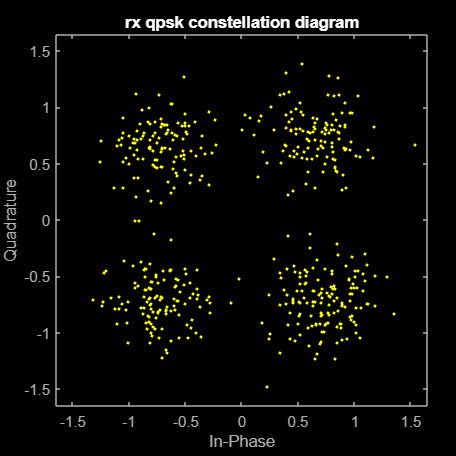

rxSymbols = rxSymbolsWithCP(cpLen+1:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);

if counter==nLoops
    figure;
    scatterplot(rxQPSKSymbols);
    title('rx qpsk constellation diagram');
end


% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(transpose(demodulatedBits)~=transpose(messageBits(1:dataLength)));
nbiot_ber(counter)=errors/dataLength;

symbolRate=samplingRate/SPS;
bitRate =  2*12*symbolRate;

SNR_linear = 10^(SNR / 10);
%Eb_N0(counter) = (SNR_linear * samplingRate) / bitRate

EbN0_sim(counter)=10*log10(SNR_linear*samplingRate/bitRate);


end
nbiot_ber
EbN0_sim

nbiot_ber =     0.1577    0.1270    0.1042    0.0843    0.0585    0.0298    0.0238    0.0159    0.0050    0.0020


EbN0_sim =     7.9897    8.9897    9.9897   10.9897   11.9897   12.9897   13.9897   14.9897   15.9897   16.9897


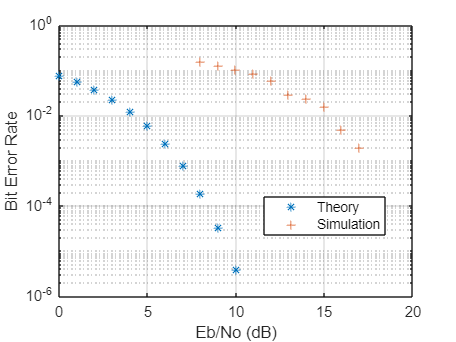

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(transpose(EbN0),ber,'*')
hold on
semilogy(transpose(EbN0_sim),nbiot_ber,'+')
legend({'Theory','Simulation'},'Location','best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on